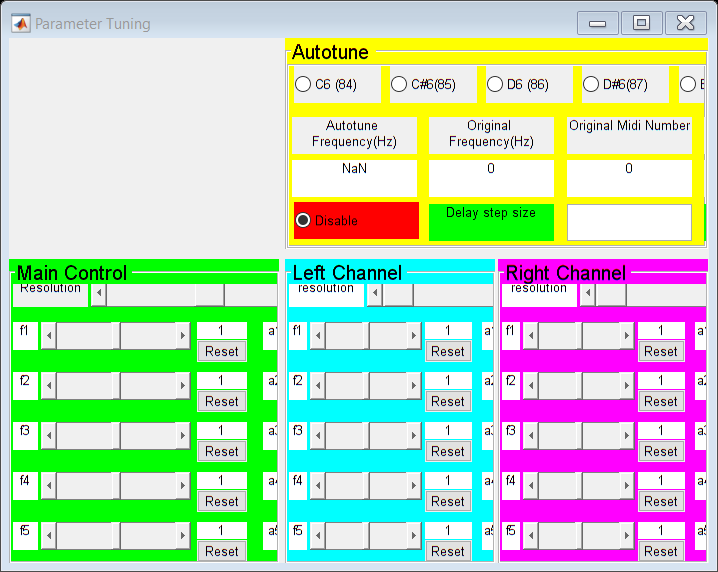

% Main figure
hMainFigure = figure( ...
    'Name','Parameter Tuning', ...
    'MenuBar','none', ...
    'Toolbar','none', ...
    'HandleVisibility','callback', ...
    'NumberTitle','off', ...
    'IntegerHandle','off');

A = imread("spectral1.png");
I =imresize(A, 0.5);
hButton = uicontrol('Parent',hMainFigure,...
                    'CData',I,'Position',[3,480,1600/2.72,900/2.72]);

p1 = uipanel('Parent',hMainFigure,'Position',[0 0 0.386 0.58],'BackgroundColor','green','Title','Main Control','FontSize',12);
p2 = uipanel('Parent',hMainFigure,'Position',[0.395 0.598 0.605 0.402],'BackgroundColor','yellow','Title','Autotune','FontSize',12);
p3 = uipanel('Parent',hMainFigure,'Position',[0.395 0 0.3 0.58],'BackgroundColor','cyan','Title','Left Channel','FontSize',12);
p4 = uipanel('Parent',hMainFigure,'Position',[0.7 0 0.3 0.58],'BackgroundColor','magenta','Title','Right Channel','FontSize',12);

autotune = parameterRef;
autotune.name = "autotune";
autotune.value = NaN;
autotune.step = 1; %flag
midi(p2,autotune);

freq_org = 0;
freqValueDisplay = uicontrol('Parent',p2, ...
        'Style','text', ...
        'Position', [115 40 100 30], ...
        'BackgroundColor','white', ...
        'String',freq_org);

midi_org = 0;
midiValueDisplay = uicontrol('Parent',p2, ...
        'Style','text', ...
        'Position', [225 40 100 30], ...
        'BackgroundColor','white', ...
        'String',freq_org);

deviation = parameterRef;
deviation.value = 2000;
deviation.step = 100;
parameterTuning_linear_nolabel(p2,deviation,0,2001,[440,75,270,26],[713,75,40,26],[756,75,50,26],[815,75,60,26],[876,75,48,26]);

set_freq = parameterRef;
set_freq.value = 300;
set_freq.step = 1;
parameterTuning_linear_nolabel(p2,set_freq,20,2000,[440,40,270,26],[713,40,40,26],[756,40,50,26],[815,40,60,26],[876,40,48,26]);

set_speed_ratio = parameterRef;
set_speed_ratio.value = 1;
set_speed_ratio.step = 0.01;
parameterTuning_nolabel(p2,set_speed_ratio,0.5,2,[440,5,270,26],[713,5,40,26],[756,5,50,26],[815,5,60,26],[876,5,48,26]);

[pitch_ratio,amplitude_ratio,beat_ratio,vibrato_width,vibrato_rate,freq_lowEnd,...
    freq_highEnd,resolution,f1,f2,f3,f4,f5,a1,a2,a3,a4,a5,t1,t2,t3,t4,t5] = main_panel(p1);

[pitch_ratio_l,amplitude_ratio_l,time_delay_l,vibrato_width_l,vibrato_rate_l,freq_lowEnd_l,...
    freq_highEnd_l,resolution_l,f1_l,f2_l,f3_l,f4_l,f5_l,a1_l,a2_l,a3_l,a4_l,a5_l,...
    t1_l,t2_l,t3_l,t4_l,t5_l] = left_panel(p3);

[pitch_ratio_r,amplitude_ratio_r,time_delay_r,vibrato_width_r,vibrato_rate_r,freq_lowEnd_r,...
    freq_highEnd_r,resolution_r,f1_r,f2_r,f3_r,f4_r,f5_r,a1_r,a2_r,a3_r,a4_r,a5_r,...
    t1_r,t2_r,t3_r,t4_r,t5_r] = left_panel(p4);

delay_stepsize = parameterRef;
delay_stepsize.value = 0.001;
Edit(p2,delay_stepsize,[225 5 100 30]);

% para_store_didadi = gen_parameter('didadi_vocal.wav');
para_store_papillon = gen_parameter('Papillon_vocal.wav');

para_store = para_store_didadi;
% para_store = para_store_papillon;
frame = 2205;
fs = 44100;
[NY,fs] = audioread('didadi_vocal.wav');
% [NY,fs] = audioread('Papillon_vocal.wav');
y = NY(:,1);
ny = length(y);

c1 = 80; %80
c2 = 350; %300
c3 = 1000;

nh = 1024;
numm_max = round(ny/frame);
len = length(para_store);

x = parameterRef; % frequency
x.value = 1;
f_speed_ratio = parameterRef;
f_speed_ratio.value = 1;
ct = parameterRef;
ct.value = 0;
x_f1 = parameterRef;
x_f1.value = 1;
x_f2 = parameterRef;
x_f2.value = 1;
x_f3 = parameterRef;
x_f3.value = 1;
x_f4 = parameterRef;
x_f4.value = 1;
x_f5 = parameterRef;
x_f5.value = 1;

x2 = parameterRef;
x2.value = 1; % amplitude
x_a1 = parameterRef;
x_a1.value = 1;
x_a2 = parameterRef;
x_a2.value = 1;
x_a3 = parameterRef;
x_a3.value = 1;
x_a4 = parameterRef;
x_a4.value = 1;
x_a5 = parameterRef;
x_a5.value = 1;

x_t1 = parameterRef;  % time delay
x_t1.value = 0;
x_t2 = parameterRef;
x_t2.value = 0;
x_t3 = parameterRef;
x_t3.value = 0;
x_t4 = parameterRef;
x_t4.value = 0;
x_t5 = parameterRef;
x_t5.value = 0;

x_auto = parameterRef;
x_auto.value = 300; % autotune frequency
store_auto = parameterRef;
store_auto.value = 300;

x_dev = parameterRef;
x_dev.value = 2000;
x_beat = parameterRef;
x_beat.value = 0;
x_vwidth = parameterRef;
x_vwidth.value = 0;
x_vrate = parameterRef;
x_vrate.value = 0;

afr = dsp.AudioFileReader('didadi_vocal.wav','SamplesPerFrame',frame);
% afr = dsp.AudioFileReader('Papillon_vocal.wav','SamplesPerFrame',frame);
adw = audioDeviceWriter('SampleRate', afr.SampleRate);
acc = audioread('didadi_accompaniment.wav');
% acc = audioread('Papillon_accompaniment.wav');

y_fof = parameterRef;
y_fof.value = zeros(1,ny+5*fs);
sst = parameterRef;
sst.value = 1;
p = parameterRef;
p.value = 1;

while sst.value < frame
    
    Parameter = para_store{p.value};
    [~,col] = size(Parameter);
    if col > 0
        for i = 1:col
            beta = Parameter(4,i);
            t = pi/beta;
            alpha = min(Parameter(3,i),c1)*pi;
            f = Parameter(1,i);
            omega = 2*pi*f;
            kn1 = [0:fs*t-1]/fs;
            s1 = (1 - cos(beta*kn1))/2.*exp(-alpha*kn1).*sin(omega*kn1);
            ts = ceil(-log(0.003)/(alpha*t));
            kn2 = [t*fs:t*fs*ts]/fs;
            s2 = exp(-alpha*kn2).*sin(omega*kn2);
            s = [s1 s2];
            
            if Parameter(3,i) > c2 && Parameter(3,i) <= c3
                s = conv(s,rand(1,length(s)+1)*2-1);
            elseif Parameter(3,i) > c3
                s = conv(s,rand(1,length(s)+1)*2-1);
                s = conv(s,rand(1,length(s)+1)*2-1);
            end
            
            s = s/max(abs(s))*Parameter(2,i);
            y_fof.value(sst.value:sst.value+length(s)-1) = y_fof.value(sst.value:sst.value+length(s)-1)+s;
        end
        
        f0 = Parameter(1,1);
        step = round(fs/f0);
        sst.value = sst.value + step;
    else
        sst.value = sst.value + nh;
    end
    p.value = p.value + 1;
    
end

t = timer;
% t.StartFcn = @(~,thisEvent)disp([thisEvent.Type ' executed '...
%     datestr(thisEvent.Data.time,'dd-mmm-yyyy HH:MM:SS.FFF')]);
t.TimerFcn = {@callback_fcn,para_store,p,set_speed_ratio,f1,f2,f3,f4,f5,a1,a2,a3,a4,a5,...
                        t1,t2,t3,t4,t5,autotune,set_freq,deviation,freqValueDisplay,midiValueDisplay,delay_stepsize,...
                        pitch_ratio,amplitude_ratio,vibrato_width,vibrato_rate,beat_ratio,x,f_speed_ratio,ct,x_f1,x_f2,x_f3,x_f4,x_f5,x2,...
                        x_a1,x_a2,x_a3,x_a4,x_a5,x_t1,x_t2,x_t3,x_t4,x_t5,x_auto,store_auto,x_dev,...
                        x_beat,x_vwidth,x_vrate,c1,c2,c3,sst,fs,y_fof,frame,len};
% t.StopFcn = @(~,thisEvent)disp([thisEvent.Type ' executed '...
%     datestr(thisEvent.Data.time,'dd-mmm-yyyy HH:MM:SS.FFF')]);
t.Period = 0.05;
t.TasksToExecute = numm_max;
t.ExecutionMode = 'fixedRate';
t.BusyMode = "queue";
% t.ErrorFcn = @(~,thisEvent)disp("Busy");
% t_draw = timer('TimerFcn',@(x,y)drawnow, 'Period', 0.05, 'TasksToExecute', numm_max, 'ExecutionMode', 'fixedRate',"BusyMode",'queue');

numm = 0;
start(t)
while numm*frame < ny+fs/2 || p.value <= len
    y_fof_out = y_fof.value;
    afr();
    audio = y_fof_out(1+numm*frame:frame+numm*frame)/50 + acc(1+numm*frame:frame+numm*frame)*x_beat.value;
    numm = numm + 1;
    adw(audio');
end

release(afr); 
release(adw);

tic
callback(para_store,p,set_speed_ratio,f1,f2,f3,f4,f5,a1,a2,a3,a4,a5,...
                        t1,t2,t3,t4,t5,autotune,set_freq,deviation,freqValueDisplay,midiValueDisplay,delay_stepsize,...
                        pitch_ratio,amplitude_ratio,vibrato_width,vibrato_rate,beat_ratio,x,f_speed_ratio,ct,x_f1,x_f2,x_f3,x_f4,x_f5,x2,...
                        x_a1,x_a2,x_a3,x_a4,x_a5,x_t1,x_t2,x_t3,x_t4,x_t5,x_auto,store_auto,x_dev,...
                        x_beat,x_vwidth,x_vrate,c1,c2,c3,sst,fs,y_fof,frame,len)
elapsedTime = toc